clear,close all,clc
bag = rosbag('2019-06-30-21-54-04.bag');

scanSel = select(bag,'Topic','/scan');
scan = readMessages(scanSel);
scants = timeseries(scanSel);

%  c=120;
%  a =round( 97/c*length(scan));
%  b = round( 107/c*length(scan));
%% read SICK laserscan

%  for i = a:2:b
%     ranges = scan{i,1}.Ranges;
%     angles = scan{i,1}.readScanAngles;
%
%
%     for k=1:length(scan{i, 1}.Intensities)
%         if scan{i, 1}.Intensities(k,1) < 200
%
%              scan{i,1}.Ranges(k,1)=single(Inf);
%
%         end
%
%     end
%      plot(scan{i,1}),hold on,axis equal
% %      i
% end

%% read velodyne laserscan
scanSel = select(bag,'Topic','/velodyne_points');

scan=readMessages(scanSel);


c = 59;
start =round( 30/c*length(scan));
b = round( 31/c*length(scan));

figure
xmin = -10;xmax=10;
for i=start:b
    i
    %     a{i} = readXYZ(scan{i});
    a = readXYZ(scan{i});

%      pcshow(a(5000:20000,:))
     for g=1:length(a)
         g
%         if a(g,3) >0
             if a(g,1) >xmin && a(g,1) <xmax && a(g,2) >-10 && a(g,2) <10
                 
                    plot(a(g,1),a(g,2),'.'),
                    hold on
%                 end
             end
         end
%         g
%     end
end

i =    300


i =    301


i =    302


i =    303


i =    304


i =    305


i =    306


i =    307


i =    308


i =    309


i =    310


i =    311


i =    312


i =    313


i =    314


i =    315


i =    316


i =    317


i =    318


i =    319


i =    320


i =    321


i =    322


i =    323


i =    324


i =    325


i =    326


i =    327


i =    328


i =    329


i =    330


i =    331


i =    332


i =    333


i =    334


i =    335


i =    336


i =    337


i =    338


i =    339


i =    340


i =    341


i =    342


i =    343


i =    344


i =    345


i =    346


i =    347


i =    348


i =    349


i =    350


i =    351


i =    352


i =    353


i =    354


i =    355


i =    356


i =    357


i =    358


i =    359


i =    360


i =    361


i =    362


i =    363


i =    364


i =    365


i =    366


i =    367


i =    368


i =    369


i =    370


i =    371


i =    372


i =    373


i =    374


i =    375


i =    376


i =    377


i =    378


i =    379


i =    380


i =    381


i =    382


i =    383


i =    384


i =    385


i =    386


i =    387


i =    388


i =    389


i =    390


i =    391


i =    392


i =    393


i =    394


i =    395


i =    396


i =    397


i =    398


i =    399


i =    400


i =    401


i =    402


i =    403


i =    404


i =    405


i =    406


i =    407


i =    408


i =    409


i =    410


i =    411


i =    412


i =    413


i =    414


i =    415


i =    416


i =    417


i =    418


i =    419


i =    420


i =    421


i =    422


i =    423


i =    424


i =    425


i =    426


i =    427


i =    428


i =    429


i =    430


i =    431


i =    432


i =    433


i =    434


i =    435


i =    436


i =    437


i =    438


i =    439


i =    440


i =    441


i =    442


i =    443


i =    444


i =    445


i =    446


i =    447


i =    448


i =    449


i =    450


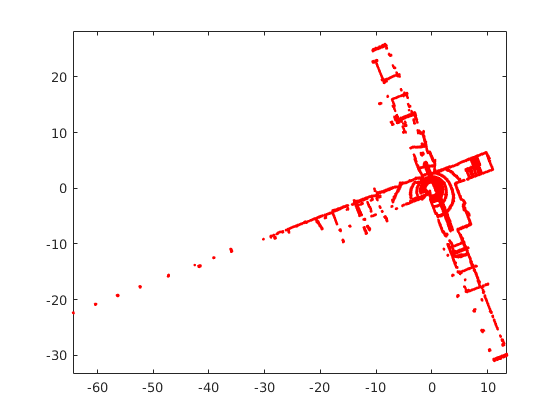

axis equal,